# **Section A**

## Data Preparation

### **Part 1**

Use the plot command to view the time series sensor data for the variables Pressure, Vibration and Temperature (PVT) and the Electrodes. Do this for several objects and trials and then choose a single time step that looks like it will allow differentiation between the data for different objects. Explain why you chose that value. Include an example of your data visualisation for one or two object trials in your report.

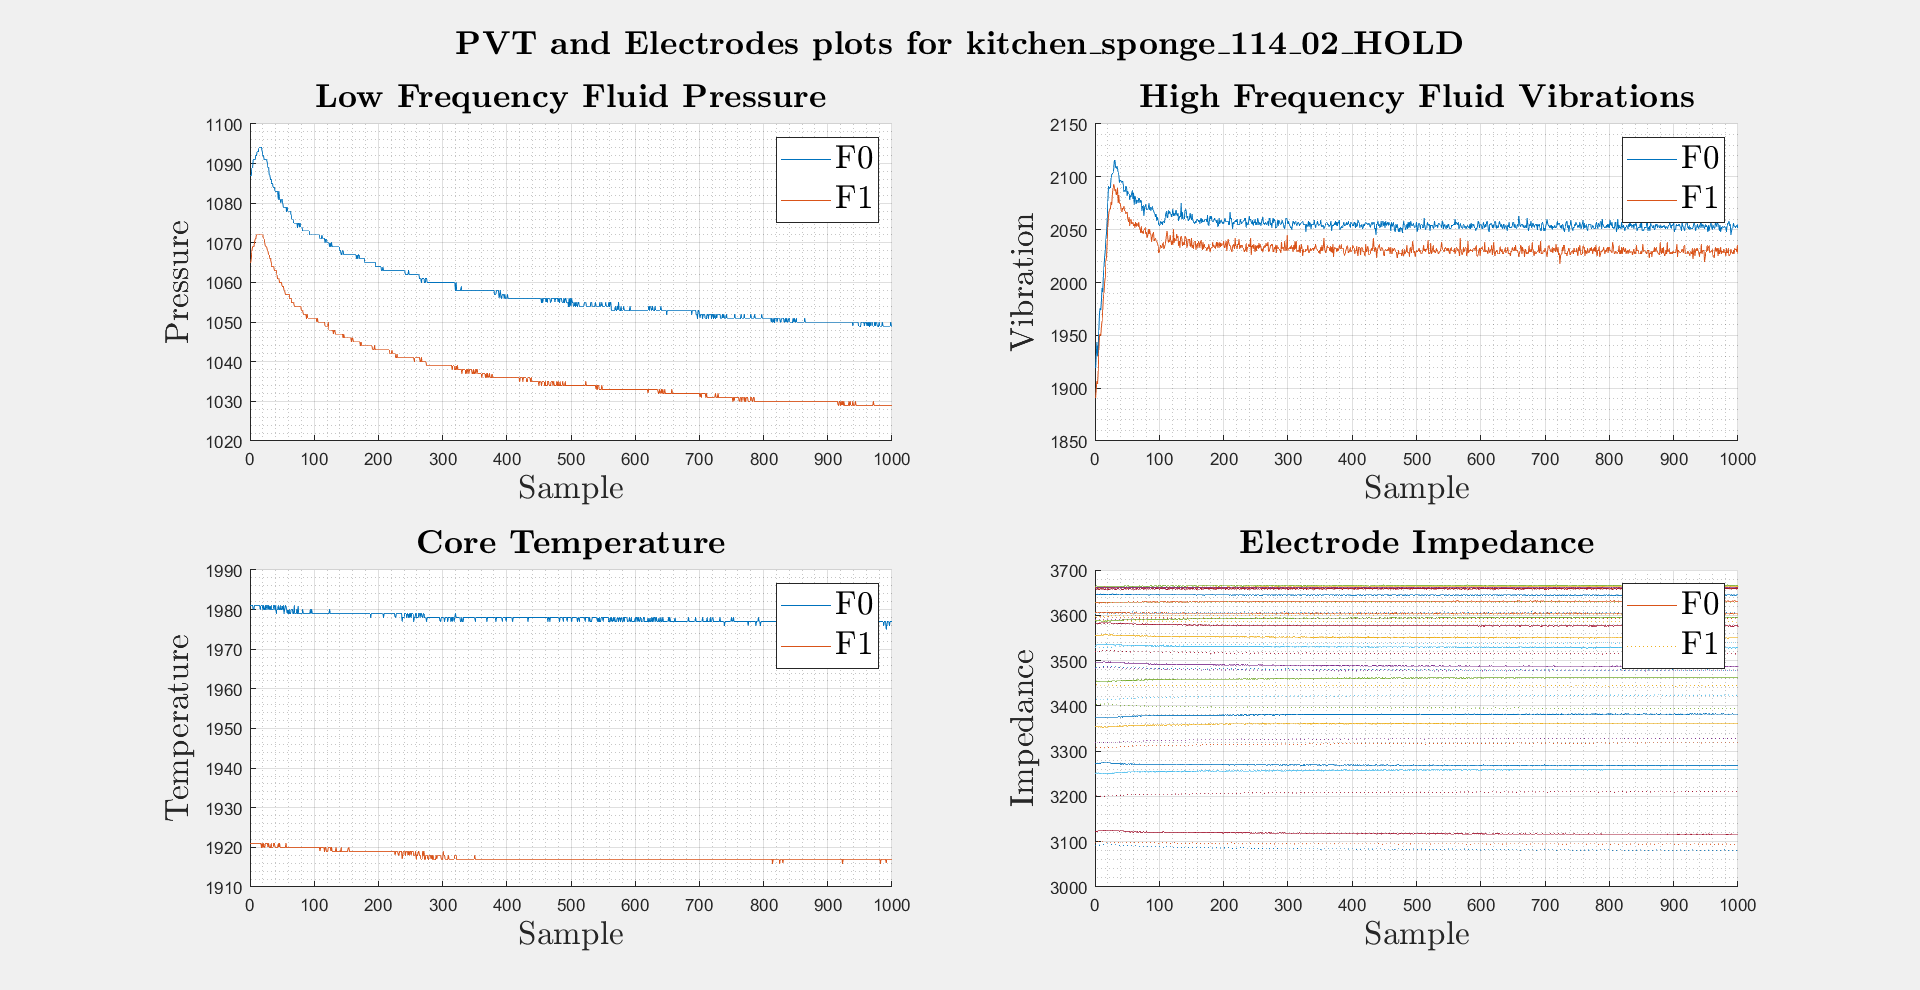

clc, clear, close all

% load data
fileName = 'kitchen_sponge_114_02_HOLD';

% kitchen_sponge_114_02_HOLD
% acrylic_211_01_HOLD
% black_foam_110_03_HOLD
% flour_sack_410_02_HOLD

load(strcat('PR_CW_DATA_2022','/',fileName,'.mat')) 

% plot pressure
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
subplot(2,2,1)
hold on
plot(F0pdc)
plot(F1pdc)
legend(['F0';'F1'],'Interpreter', 'Latex', 'Fontsize', 20)
grid on
grid minor
xlabel('Sample','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Pressure','Interpreter', 'Latex', 'Fontsize', 20)
title('\textbf{Low Frequency Fluid Pressure}','Interpreter', 'Latex', 'Fontsize', 20)

% plot vibration
subplot(2,2,2)
hold on
plot(F0pac(2,:))
plot(F1pac(2,:))
legend(['F0';'F1'],'Interpreter', 'Latex', 'Fontsize', 20)
grid on
grid minor
xlabel('Sample','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 20)
title('\textbf{High Frequency Fluid Vibrations}','Interpreter', 'Latex', 'Fontsize', 20)

% plot temperature 
subplot(2,2,3)
hold on
plot(F0tdc)
plot(F1tdc)
legend(['F0';'F1'],'Interpreter', 'Latex', 'Fontsize', 20)
grid on
grid minor
xlabel('Sample', 'Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Temperature', 'Interpreter', 'Latex', 'Fontsize', 20)
title('\textbf{Core Temperature}','Interpreter', 'Latex', 'Fontsize', 20)

% plot impedance 
subplot(2,2,4)
hold on
for row= 1:19
    h1 = plot(F0Electrodes(row,:), 'LineStyle','-');
    h2 = plot(F1Electrodes(row,:), 'LineStyle',':');
end
grid on
grid minor
legend([h1 h2],'F0','F1','Interpreter', 'Latex', 'Fontsize', 20)
xlabel('Sample', 'Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Impedance', 'Interpreter', 'Latex', 'Fontsize', 20)
title('\textbf{Electrode Impedance}','Interpreter', 'Latex', 'Fontsize', 20)

% saveas(gca, fullfile('figures', 'pr_a_1'), 'epsc2');

fileNameTitle = strrep(fileName, '_', '\_');
sgtitle(['\textbf{PVT and Electrodes plots for ',fileNameTitle, '}'], 'Fontsize', 20, 'Interpreter', 'Latex')

hold off;

### Part 2

For one finger (F0 or F1), sample the Pressure, Vibration, Temperature time series data into scalar values measured at the time instance (of your selected time step) for each object / trial. Save the data structures together as a .mat file called F0_PVT.mat or F1_PVT.mat. Repeat for the Electrodes data, saving that as another .mat file. Note that all subsequent actions in this coursework will be on the data sets you just created (and therefore only on one of the robot’s fingers).

dirName = 'PR_CW_DATA_2022';
timestep = 25;                                 % sample to use for comparison
PVT = struct;                                   %  struct for data for all materials at chosen timestep
Electrodes = struct;
myDir = dirName;
myFiles = dir(fullfile(dirName,'*.mat'));       % get all mat files in directory
for k = 1:length(myFiles)
  baseFileName = myFiles(k).name;
  fullFileName = fullfile(myDir, baseFileName);
  load(fullFileName);
  % read data from each file into structs - change 'F0' to 'F1' to get data for different finger
  PVT(k).name = baseFileName;
  PVT(k).pressure = F0pdc(timestep);
  PVT(k).vibration = F0pac(2,timestep);
  PVT(k).temperature = F0tdc(timestep);
  Electrodes(k).name = baseFileName;
  Electrodes(k).impedance = F0Electrodes(:,timestep);
  save('F0_PVT.mat', 'PVT')
  save('F0_Electrodes.mat', 'Electrodes')
end

### Part 3

Create a 3D scatter plot of the complete contents of the PVT .mat file, with the axis as Pressure, Vibration and Temperature, with different colours used for different objects. Use the same colours for the objects throughout this work.

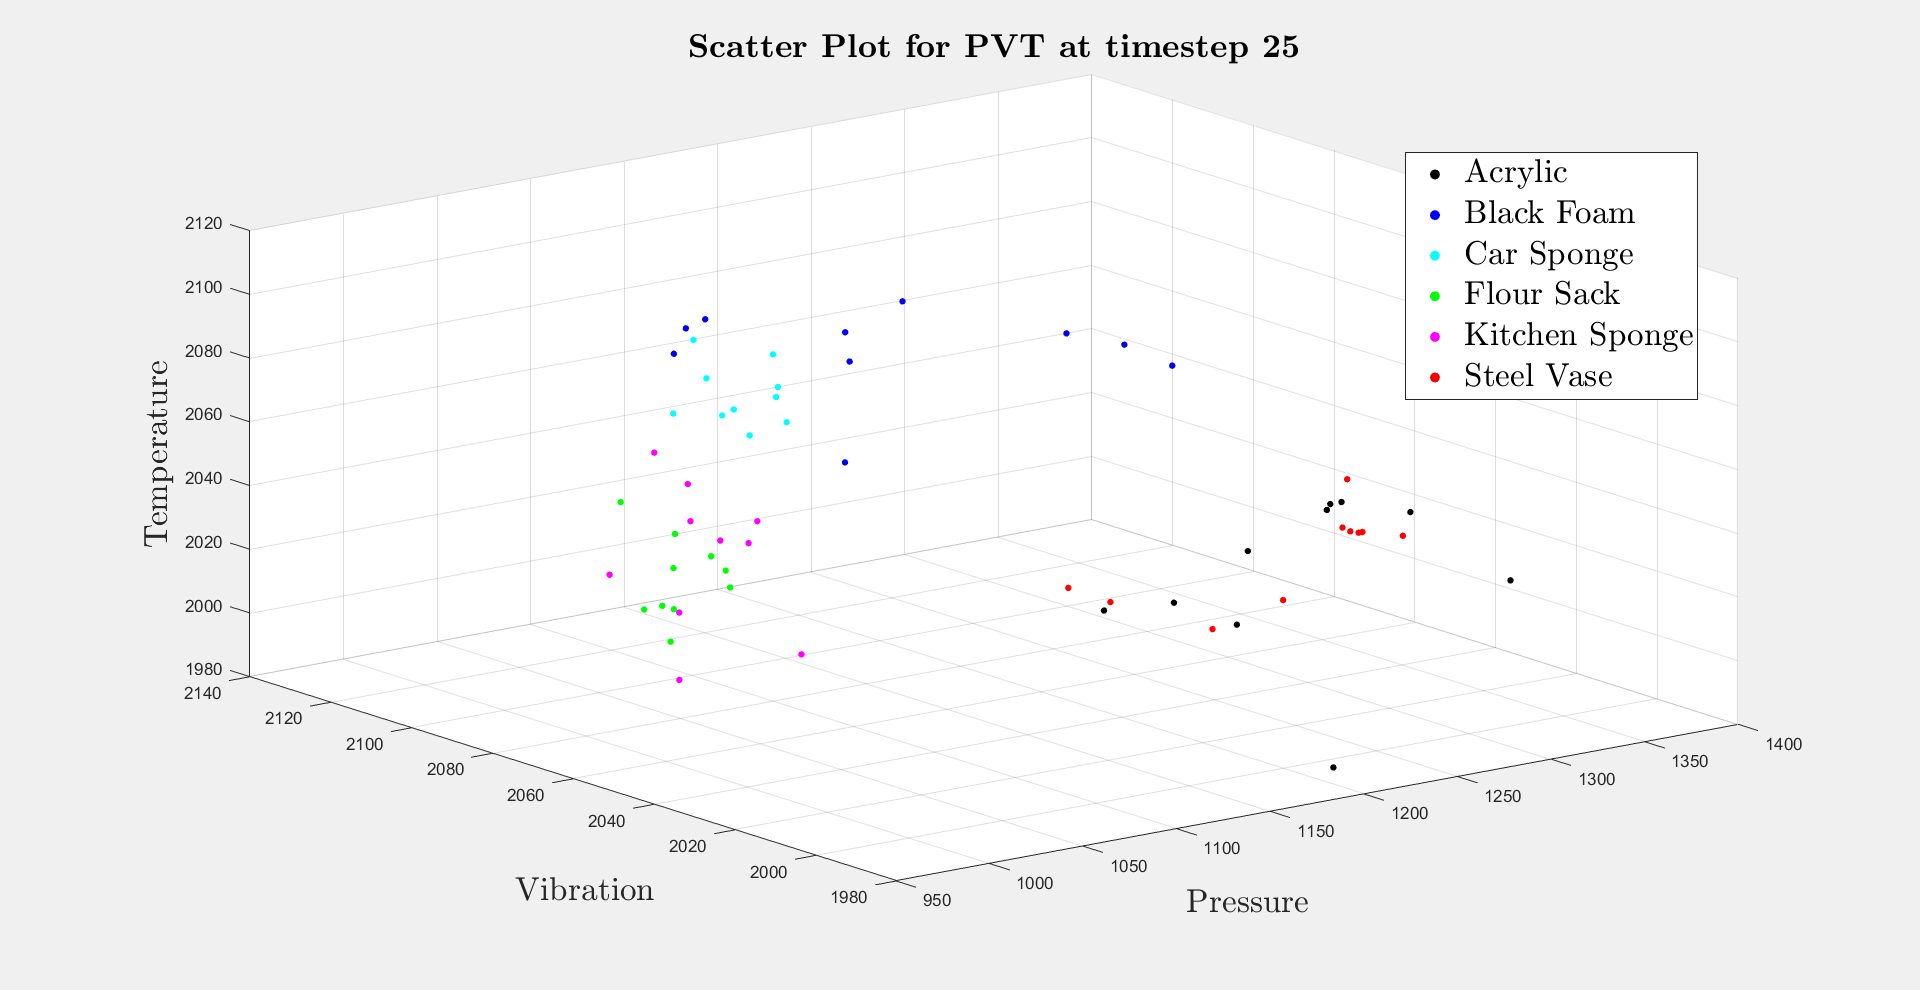

% load data
F0_PVT = load('F0_PVT.mat').PVT;
F0_Electrodes = load('F0_Electrodes.mat').Electrodes;

pressure = zeros(1,60);
vibration = zeros(1,60);
temperature = zeros(1,60);

% get data into individual variables
for i = 1:60
    pressure(i) = F0_PVT(i).pressure;
    vibration(i) = F0_PVT(i).vibration;
    temperature(i) = F0_PVT(i).temperature;
end

colourNames = {'black', 'blue', 'cyan', 'green', 'magenta', 'red'};

% scatter plot
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
scatter3(pressure(1:10),vibration(1:10),temperature(1:10),15, colourNames{1},'filled')
hold on;
for i = 1:5
    scatter3(pressure((i*10)+1:(i+1)*10),vibration((i*10)+1:(i+1)*10),temperature((i*10)+1:(i+1)*10),15,colourNames{i+1},'filled')
end

xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 20)
zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 20)
legend('Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase','Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
title(['\textbf{Scatter Plot for PVT at timestep ', num2str(timestep), '}'],'Interpreter', 'Latex', 'Fontsize', 20)
hold off;

% saveas(gca, fullfile('figures', 'pr_a_2'), 'epsc2');


# **Section B**

## Principal Component Analysis

### Part 1

Using PCA (Principal Component Analysis) determine the principal components of the PVT data.

**a) Report covariance matrix, eigenvalues, and eigenvectors for the data.**

% get the covariance matrix
Q = [pressure;vibration;temperature];
Q = Q';

A = [pressure;vibration;temperature];
C = cov(A');                 % C = covariance matrix



% finding Eigenvectors
[V,D] = eig(C);         % V = the corresponding eigenvectors 
D=diag(D);              % these are the corresponding eigenvalues

% returns the eigenvector for the maximum eigenvalue
maxeigval= V(:,find(D==max(D))); 

% standardize the data
A = bsxfun(@minus,A',mean(A'))./ std(A');

% Do the PCA
[coeff,score,latent] = pca(A); % coeff = feature vector for eigenvectors

% Calculate eigenvalues and eigenvectors of the covariance matrix
SC = cov(A);

[SV,SD] = eig(SC);
SD=diag(SD);

coeff = coeff*-1;   % compared to SV and SD the eigenvector were multiplied by -1 except the last column (unknown why)
coeff(:,end) = coeff(:,end)*-1; % the last eigenvector was as supposed to be so returning it to original

**b) Replot the Standardised data with the Principal components displayed.**

% Re-plot scatter plot for standardized data
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
scatter3(A((1:10),1),A((1:10),2),A((1:10),3),15, colourNames{1},'filled')
hold on;
for i = 1:5
    scatter3(A(((i*10)+1:(i+1)*10),1),A(((i*10)+1:(i+1)*10),2),A(((i*10)+1:(i+1)*10),3),15,colourNames{i+1},'filled')
end
vbls = {'PC1','PC2','PC3'}; % Labels for the variables
bip = biplot(coeff(:,1:3),'VarLabels',vbls); % plot the PC in the scatter plot
for k = 7:9
    bip(k).FontSize = 16;
end
grid on
grid minor
xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 20)
zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 20)
legend('Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase','Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
title(['\textbf{Standardized 3D Scatter Plot for PCA at timestep ', num2str(timestep), '}'], 'Interpreter', 'Latex', 'Fontsize', 20)
hold off
% saveas(gca, fullfile('figures', 'pr_b_1'), 'epsc2');

#### c) Reduce the data to 2-dimensions and replot.

PC3_coeff = coeff(:,end); %Get last column as PC3
PC2_coeff = coeff(:,2);   %Get SECOND column as PC2
PC1_coeff = coeff(:,1);   %Get FIRST column as PC1

% Create projected matrix onto the Principle Components
coeff(:,end) = []; % Delete last column to get feature vector for 2D data
P = A*coeff;    % Get 2D projected data

% Re-plot scatter plot for standardized data
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
scatter(P((1:10),1),P((1:10),2),15, colourNames{1},'filled')
hold on;
for i = 1:5
    scatter(P(((i*10)+1:(i+1)*10),1),P(((i*10)+1:(i+1)*10),2),15,colourNames{i+1},'filled')
end

axis([-3 3 -3 3])
grid on
grid minor
xlabel('PC1','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('PC2','Interpreter', 'Latex', 'Fontsize', 20)
legend('Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase','Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
title('\textbf{Standardized 2D scatter plot for PCA}', 'Interpreter', 'Latex', 'Fontsize', 28)
% saveas(gca, fullfile('figures', 'pr_b_2'), 'epsc2');

#### d) Show how the data is distributed across all principal components by plotting as separate 1D number lines.

PC1 = A*PC1_coeff;  % Project onto PC1 to get 1D Data
PC2 = A*PC2_coeff;  % Project onto PC2 to get 1D Data
PC3 = A*PC3_coeff;  % Project onto PC3 to get 1D Data

% Create projected matrix onto the Principle Components
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
hAxes = axes('NextPlot','add', 'DataAspectRatio',[1 1 1], 'YLim',[0.5 3.5], 'Color','white');

legNames = {'Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase'};

plotHandles = zeros(6,10);

hold on
    for i = 1:6
        plotHandles(i,:) = scatter(hAxes, PC1(((i-1)*10)+1:i*10),1,colourNames{i}, 'filled');
        scatter(hAxes, PC2(((i-1)*10)+1:i*10),2,colourNames{i}, 'filled');  %# Plot data set 2 (show at y = 2)
        scatter(hAxes, PC3(((i-1)*10)+1:i*10),3,colourNames{i}, 'filled');  %# Plot data set 3 (show at y = 3) 
    end
hold off

legend(plotHandles(:,1), legNames,'Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')

grid on
grid minor
yticks([1, 2, 3]) % Show only ticks for the 3 PC
yticklabels({'PC1', 'PC2', 'PC3'}) % Replace tick values with PC names
a = get(gca,'YTickLabel');
set(gca,'YTickLabel',a, 'fontsize',18)
title('\textbf{1D PCA Plots for F0 PVT Data}', 'Interpreter', 'Latex', 'Fontsize', 20)
% saveas(gca, fullfile('figures', 'pr_b_3'), 'epsc2');

### Part 2

There are 19 electrodes per sensor, so relationship between the electrodes for different objects cannot be easily visualised as in the last questions.

#### a) Use PCA to determine the principal components of the electrode data. Report on the variances of each principal components using a Scree plot.

% Get electrodes data for one finger (F0) - same as for PVT
labels = zeros(1,60);
features = zeros(19,60);
for i = 1:60
    features(:,i) = F0_Electrodes(i).impedance;
    labels(i) = floor((i-1)/10);
    %E = [E; {F0_Electrodes_500(v).impedance}];
end

E = features;

% standardize the data
E = bsxfun(@minus,E',mean(E'))./ std(E');

% Calculate eigenvalues and eigenvectors of the covariance matrix
SCE = cov(E);
[SVE,SDE] = eig(SCE);
SDE=diag(SDE);
maxeigvalE= SVE(:,find(SDE==max(SDE))); % Get first PC eigenvector

% Get variance of each component by finding corresponding eigenvalues
[Ecoeff, Escore, eigenvalues] = pca(E); % Check that variables match with eigenvectors and eigenvalues found

% Make scree plot of PC 
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
plot(eigenvalues, 'b*-', 'MarkerSize',10); % Plot Eigenvalues per Component Number
hold on
yline(eigenvalues(3), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 3)
grid on
grid minor
xlabel('Component Number','Interpreter', 'Latex', 'Fontsize', 20) 
ylabel('Eigenvalues','Interpreter', 'Latex', 'Fontsize', 20)
set(gca,'YTick',0:1:15) % Set more ticks in y-axis
title('\textbf{Variance PCA Scree Plot for F0 Electrode Data}','Interpreter', 'Latex', 'Fontsize', 20)
% saveas(gca, fullfile('figures', 'pr_b_4'), 'epsc2');

#### b) Visualize the electrode data using the three principal components with largest variance.

% Visualise data with first 3 PC
PC3_Ecoeff = Ecoeff(:,3); % Get THIRD column as PC3
PC2_Ecoeff = Ecoeff(:,2); % Get SECOND column as PC2
PC1_Ecoeff = Ecoeff(:,1); % Get FIRST column as PC1
EPC1 = E*PC1_Ecoeff;     % Project data onto PC1 as 1D
EPC2 = E*PC2_Ecoeff;     % Project data onto PC2 as 1D
EPC3 = E*PC3_Ecoeff;     % Project data onto PC3 as 1D

J = [EPC1 EPC2 EPC3]; % Combine projected data onto PC vectors into one data matrix
J_coeff = [PC1_Ecoeff PC2_Ecoeff PC3_Ecoeff]; % Combine PC vectors into one data matrix

electrodes_data = [labels' J];

% Plot the 3D projected Data onto top 3 variance PC
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')

scatter3(J((1:10),1),J((1:10),2),J((1:10),3),15, colourNames{1},'filled')
hold on;
for i = 1:5
    scatter3(J(((i*10)+1:(i+1)*10),1),J(((i*10)+1:(i+1)*10),2),J(((i*10)+1:(i+1)*10),3),15,colourNames{i+1},'filled')
end
grid on
grid minor
xlabel('PC1','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('PC2','Interpreter', 'Latex', 'Fontsize', 20)
zlabel('PC3','Interpreter', 'Latex', 'Fontsize', 20)
legend('Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase','Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
axis([-6 6 -6 6 -6 6])
axis square
title('\textbf{Projection for first 3 PC of Electrode Data}','Interpreter', 'Latex', 'Fontsize', 20)
% saveas(gca, fullfile('figures', 'pr_b_4'), 'epsc2');

% Create projected matrix onto the Principle Components 1D
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
hAxes = axes('NextPlot','add','DataAspectRatio',[1 1 1],'YLim',[0 20],'Color','white');

plotHandles = zeros(6,10);

hold on
    for i = 1:6
        plotHandles(i,:) = scatter(hAxes, EPC1(((i-1)*10)+1:i*10),5,colourNames{i}, 'filled');
        scatter(hAxes, EPC2(((i-1)*10)+1:i*10),10,colourNames{i}, 'filled');  %# Plot data set 2 (show at y = 2)
        scatter(hAxes, EPC3(((i-1)*10)+1:i*10),15,colourNames{i}, 'filled');  %# Plot data set 3 (show at y = 3) 
    end
hold off

legend(plotHandles(:,1), legNames,'Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
grid on
grid minor
xlim([-10 10])
yticks([5, 10, 15]) % Show only ticks for the 3 PC
yticklabels({'PC1', 'PC2', 'PC3'}) % Replace tick values with PC names
a = get(gca,'YTickLabel');
set(gca,'YTickLabel',a, 'fontsize',18)
title('\textbf{1D PCA Plots for F0 Electrodes}', 'Interpreter', 'Latex', 'Fontsize', 20)
% saveas(gca, fullfile('figures', 'pr_b_4'), 'epsc2');

# **Section C**

We want to see if we can discriminate two deformable and porous objects by touch: the black foam and the car sponge. 

### Part 1 Carlota			

Use LDA to split the training data in terms of Pressure vs. Vibration, Pressure vs. Temperature and Temperature vs. Vibration. Plot the results, including a line showing the generated LDA function. 

% % load("F0_PVT.mat")
% %load('Sara_data/F0_PVT.mat')
% 
% bfoam = zeros(3, 10); 
% csponge = zeros(3, 10); 
% for i=1:10
%     bfoam(1,i) = PVT(i+10:i+19).pressure;
%     bfoam(2,i) = PVT(i+10:i+19).vibration;
%     bfoam(3,i) = PVT(i+10:i+19).temperature;
%     csponge(1,i) = PVT(i+20:i+29).pressure;
%     csponge(2,i) = PVT(i+20:i+29).vibration;
%     csponge(3,i) = PVT(i+20:i+29).temperature;
% end    
% 
% % Pressure vs. Vibration,
% PV_bf = bfoam(1:2,:);
% PV_cs = csponge(1:2,:);
% 
% % Pressure vs. Temperature
% PT_bf = bfoam([1,3],:);
% PT_cs = csponge([1,3],:);
% 
% % Temperature vs. Vibration
% TV_bf = bfoam([3,2],:);
% TV_cs = csponge([3,2],:);
% 
% 
% % For P vs V
% 
% % standardize the data
% PV_bf_norm = normalize(PV_bf,2);
% PV_cs_norm = normalize(PV_cs,2);
% 
% % Get mean
% m_bf = mean(PV_bf_norm,2);
% m_cs = mean(PV_cs_norm,2);
% m = mean([m_bf, m_cs],2);
% 
% % scatter matrices
% Sw_s = sum(sum((repmat(m_cs,1,10)-PV_cs_norm)*(repmat(m_cs,1,10)-PV_cs_norm)'));
% Sw_f = sum(sum((repmat(m_bf,1,10)-PV_bf_norm)*(repmat(m_bf,1,10)-PV_bf_norm)'));
% Sw = Sw_s + Sw_f;
% Sb = (m_cs-m_bf)*(m_cs-m_bf)';
% [vec, ~] = eig(pinv(Sw)*Sb);
% 
% % plot(PV_bf(:,1),PV_bf(:,2),'.cyan','MarkerSize',12)
% plot(PV_bf_norm(1,:),PV_bf_norm(2,:),'.cyan','MarkerSize',12)
% hold on;
% plot(PV_cs_norm(1,:),PV_cs_norm(2,:),'.k','MarkerSize',12)
% plot([-vec(1,2)*2.5 vec(1,2)*2.5 ],...
% [-vec(2,2)*2.5 vec(2,2)*2.5 ],...
% 'Color','k','lineWidth',1.5)
% xlim([-2.5 2.5])
% ylim([-2.5 2.5])
% xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
% ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 14)
% title('\textbf{LDA Pressure vs. Vibration}','Interpreter', 'Latex', 'Fontsize', 14);
% legend(['Black Foam';'Car Sponge'],'Interpreter', 'Latex', 'Fontsize', 10)
% grid on;
% hold off;
% 
% % P vs T
% % standardize the data
% PT_bf_norm = normalize(PT_bf,2);
% PT_cs_norm = normalize(PT_cs,2);
% 
% m_bf = mean(PT_bf_norm,2);
% m_cs = mean(PT_cs_norm,2);
% m = mean([m_bf, m_cs],2);
% 
% % scatter matrices
% Sw_s = sum(sum((repmat(m_cs,1,10)-PT_cs_norm)*(repmat(m_cs,1,10)-PT_cs_norm)'));
% Sw_f = sum(sum((repmat(m_bf,1,10)-PT_bf_norm)*(repmat(m_bf,1,10)-PT_bf_norm)'));
% Sw = Sw_s + Sw_f;
% Sb = (m_cs-m_bf)*(m_cs-m_bf)';
% [vec, val] = eig(pinv(Sw)*Sb);
% 
% plot(PT_bf_norm(1,:),PT_bf_norm(2,:),'.cyan','MarkerSize',12)
% hold on;
% plot(PT_cs_norm(1,:),PT_cs_norm(2,:),'.k','MarkerSize',12)
% plot([-vec(1,2)*2.5 vec(1,2)*2.5 ],...
% [-vec(2,2)*2.5 vec(2,2)*2.5 ],...
% 'Color','k','lineWidth',1.5)
% xlim([-2.5 2.5])
% ylim([-2.5 2.5])
% xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
% ylabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
% title('\textbf{LDA Pressure vs. Vibration}','Interpreter', 'Latex', 'Fontsize', 14);
% legend(['Black Foam';'Car Sponge'],'Interpreter', 'Latex', 'Fontsize', 10)
% grid on;
% hold off;
% 
% % %% CHECK 1D Projection:
% % % Project data onto line:
% % P_bf = PT_bf_norm'*vec(:,2);    % Get 1D projected data
% % P_cs = PT_cs_norm'*vec(:,2);    % Get 1D projected data
% % plot(P_bf',zeros(1,10),'.','MarkerSize',10)
% % hold on;
% % plot(P_cs',zeros(1,10),'.','MarkerSize',10)
% % grid on;
% % hold off;
% 
% 
% % T vs V
% % standardize the data
% TV_bf_norm = normalize(TV_bf,2);
% TV_cs_norm = normalize(TV_cs,2);
% 
% % Get mean
% m_bf = mean(TV_bf_norm,2);
% m_cs = mean(TV_cs_norm,2);
% m = mean([m_bf, m_cs],2);
% 
% % scatter matrices
% Sw_s = sum(sum((repmat(m_cs,1,10)-TV_cs_norm)*(repmat(m_cs,1,10)-TV_cs_norm)'));
% Sw_f = sum(sum((repmat(m_bf,1,10)-TV_bf_norm)*(repmat(m_bf,1,10)-TV_bf_norm)'));
% Sw = Sw_s + Sw_f;
% Sb = (m_cs-m_bf)*(m_cs-m_bf)';
% [vec, ~] = eig(pinv(Sw)*Sb);
% 
% % plot(TV_bf_norm(1,:),TV_bf_norm(2,:),'.red','MarkerSize',12)
% plot(TV_bf_norm(1,:),TV_bf_norm(2,:),'.cyan','MarkerSize',12)
% hold on;
% plot(TV_cs_norm(1,:),TV_cs_norm(2,:),'.k','MarkerSize',12)
% plot([-vec(1,2)*2.5 vec(1,2)*2.5 ],...
% [-vec(2,2)*2.5 vec(2,2)*2.5 ],...
% 'Color','k','lineWidth',1.5)
% xlim([-2.5 2.5])
% ylim([-2.5 2.5])
% xlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
% ylabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
% title('\textbf{LDA Temperature vs. Pressure}','Interpreter', 'Latex', 'Fontsize', 14);
% legend(['Black Foam';'Car Sponge'],'Interpreter', 'Latex', 'Fontsize', 10)
% grid on;
% hold off;

Part 1 Me

% isolate data for black foam and car sponge
names = [];
pressure = [];
vibration = [];
temperature = [];

for i = 11:20
    names(i-10) = 0;
    pressure(i-10) = F0_PVT(i).pressure;
    vibration(i-10) = F0_PVT(i).vibration;
    temperature(i-10) = F0_PVT(i).temperature;
end
for i = 21:30
    names(i-10) = 1;
    pressure(i-10) = F0_PVT(i).pressure;
    vibration(i-10) = F0_PVT(i).vibration;
    temperature(i-10) = F0_PVT(i).temperature;
end

% 1 - Split the training data in terms of different pairs of variables, perform LDA and plot

% LDA pressure-vibration
PV = [pressure;vibration]';
PV_std = bsxfun(@minus,PV,mean(PV))./ std(PV); % standardise data
MdlLinearPV = fitcdiscr(PV_std,names);
K_PV = MdlLinearPV.Coeffs(1,2).Const;  
L_PV = MdlLinearPV.Coeffs(1,2).Linear;

% LDA pressure-temperature
PT = [pressure;temperature]';
PT_std = bsxfun(@minus,PT,mean(PT))./ std(PT); % standardise data
MdlLinearPT = fitcdiscr(PT_std,names);
K_PT = MdlLinearPT.Coeffs(1,2).Const;  
L_PT = MdlLinearPT.Coeffs(1,2).Linear;

% LDA temperature-vibration
TV = [temperature;vibration]';
TV_std = bsxfun(@minus,TV,mean(TV))./ std(TV);% standardise data
MdlLinearTV = fitcdiscr(TV_std,names);
K_TV = MdlLinearTV.Coeffs(1,2).Const;  
L_TV = MdlLinearTV.Coeffs(1,2).Linear;


% plot pressure-vibration
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
subplot(3,1,1);
gscatter(PV_std(:,1),PV_std(:,2),names)
hold on
xlabel('pressure')
ylabel('vibration')
legend('black foam','car sponge','Location','southwest')
title('Scatter Plot with LDA Discriminant Line for Vibration-Pressure')
f_PV = @(x1,x2) K_PV + L_PV(1)*x1 + L_PV(2)*x2;
h1 = fimplicit(f_PV);
set(h1,'Color','k','LineWidth',1,'DisplayName','decision boundary')
grid on

% plot pressure-temperature
subplot(3,1,2);
gscatter(PT_std(:,1),PT_std(:,2),names)
hold on
xlabel('pressure')
ylabel('temperature')
legend('black foam','car sponge','Location','southwest')
title('Scatter Plot with LDA Discriminant Line for Temperature-Pressure')
f_PT = @(x1,x2) K_PT + L_PT(1)*x1 + L_PT(2)*x2;
h2 = fimplicit(f_PT);
set(h2,'Color','k','LineWidth',1,'DisplayName','decision boundary')
grid on
grid minor
xlim([-2,1.5])
ylim([-5,5])

% plot temperature-vibration
subplot(3,1,3);
gscatter(TV_std(:,1),TV_std(:,2),names)
hold on
xlabel('temperature')
ylabel('vibration')
legend('black foam','car sponge','Location','southwest')
title('Scatter Plot with LDA Discriminant Line for Vibration-Temperature')
f_TV = @(x1,x2) K_TV + L_TV(1)*x1 + L_TV(2)*x2;
h3 = fimplicit(f_TV);
set(h3,'Color','k','LineWidth',1,'DisplayName','decision boundary')
xlim([-2,1.5])
ylim([-5,5])
grid on
grid minor
% saveas(gca, fullfile('figures', 'pr_c_1'), 'epsc2');

### Part 2 Carlota

Now apply LDA to the three-dimensional PVT data. Comment on the different outcomes. Consider the physical properties of the objects in your answer and how these may have affected the sensor readings. 	

% % standardize the data
% bf_norm = normalize(bfoam,2);
% cs_norm = normalize(csponge,2);
% 
% % Get mean
% m_bf = mean(bf_norm,2);
% m_cs = mean(cs_norm,2);
% m = mean([m_bf, m_cs],2);
% 
% % scatter matrices
% Sw_s = sum(sum((repmat(m_cs,1,10)-cs_norm)*(repmat(m_cs,1,10)-cs_norm)'));
% Sw_f = sum(sum((repmat(m_bf,1,10)-bf_norm)*(repmat(m_bf,1,10)-bf_norm)'));
% Sw = Sw_s + Sw_f;
% Sb = (m_cs-m_bf)*(m_cs-m_bf)';
% [vec, val] = eig(pinv(Sw)*Sb);
% 
% scatter3(bf_norm(1,:),bf_norm(2,:),bf_norm(3,:),'.red','SizeData',60)
% hold on;
% scatter3(cs_norm(1,:),cs_norm(2,:),cs_norm(3,:),'.k','SizeData',60)
% x = [-vec(1,3) -vec(1,2) vec(1,3) vec(1,2)]*20;
% y = [-vec(2,3) -vec(2,2) vec(2,3) vec(2,2)]*20;
% z = [-vec(3,3) -vec(3,2) vec(3,3) vec(3,2)]*20;
% patch(x,y,z,'red','facealpha',0.1)
% xlim([-3 3])
% ylim([-3 3])
% zlim([-3 3])
% xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
% ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 14)
% zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
% title('\textbf{LDA - Black Foam vs. Car Sponge}','Interpreter', 'Latex', 'Fontsize', 14);
% legend(['Black Foam';'Car Sponge'],'Interpreter', 'Latex', 'Fontsize', 10,'Location', 'best')
% grid on;
% hold off;	

Part 2 me

% LDA pressure-vibration-temperature
PVT = [pressure;vibration;temperature]';
PVT_std = bsxfun(@minus,PVT,mean(PVT))./ std(PVT);% standardise data
MdlLinearPVT = fitcdiscr(PVT_std,names);
K_PVT = MdlLinearPVT.Coeffs(1,2).Const;  
L_PVT = MdlLinearPVT.Coeffs(1,2).Linear;

% plot pressure-vibration-temperature
colors = 'rgb';
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
scatter3(PVT_std(1:10,1),PVT_std(1:10,2),PVT_std(1:10,3),colors(1),'filled')
hold on
scatter3(PVT_std(11:20,1),PVT_std(11:20,2),PVT_std(11:20,3),colors(2),'filled')
grid on
grid minor
xlabel('pressure')
ylabel('vibration')
zlabel('temperature')
title('Scatter Plot with LDA Discriminant Surface for Pressure-Vibration-Temperature')
hold on
f_PVT = @(x1,x2) K_PVT + L_PVT(1)*x1 + L_PVT(2)*x2;
s1 = fsurf(f_PVT,'FaceColor',[0 0 1],'EdgeColor','none');
set(s1,'DisplayName','decision boundary')
alpha 0.5
grid on
grid minor
legend('black foam','car sponge','decision surface','Location','northeast')
% saveas(gca, fullfile('figures', 'pr_c_2'), 'epsc2');

### Part 3 Carlota

Repeat the LDA analysis with your own choice of two objects. Explain why you have selected those objects for analysis. In other words – what were you trying to test and what did you determine? 	

% Try Flour Sack and Acrylic
% 
% fsack = zeros(3, 10); 
% acrylic = zeros(3, 10);
% for i=1:10
%     fsac(1,i) = PVT(i+30:i+39).pressure;
%     fsac(2,i) = PVT(i+30:i+39).vibration;
%     fsac(3,i) = PVT(i+30:i+39).temperature;
%     acrylic(1,i) = PVT(i:i+9).pressure;
%     acrylic(2,i) = PVT(i:i+9).vibration;
%     acrylic(3,i) = PVT(i:i+9).temperature;
% end   
% 
% % standardize the data
% fsack_norm = normalize(fsac,2);
% acrylic_norm = normalize(acrylic,2);
% 
% % Get mean
% m_fs = mean(fsack_norm,2);
% m_a = mean(acrylic_norm,2);
% m = mean([m_fs, m_a],2);
% 
% % scatter matrices
% Sw_s = sum(sum((repmat(m_fs,1,10)-fsack_norm)*(repmat(m_fs,1,10)-fsack_norm)'));
% Sw_f = sum(sum((repmat(m_a,1,10)-acrylic_norm)*(repmat(m_a,1,10)-acrylic_norm)'));
% Sw = Sw_s + Sw_f;
% Sb = (m_fs-m_a)*(m_fs-m_a)';
% [vec, val] = eig(pinv(Sw)*Sb);
% 
% scatter3(fsack_norm(1,:),fsack_norm(2,:),fsack_norm(3,:),'.green','SizeData',60)
% hold on;
% scatter3(acrylic_norm(1,:),acrylic_norm(2,:),acrylic_norm(3,:),'.k','SizeData',60)
% x = [-vec(1,3) -vec(1,2) vec(1,3) vec(1,2)]*20;
% y = [-vec(2,3) -vec(2,2) vec(2,3) vec(2,2)]*20;
% z = [-vec(3,3) -vec(3,2) vec(3,3) vec(3,2)]*20;
% patch(x,y,z,'red','facealpha',0.1)
% xlim([-3 3])
% ylim([-3 3])
% zlim([-3 3])
% xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
% ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 14)
% zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
% title('\textbf{LDA - Flour Sack vs. Acrylic}','Interpreter', 'Latex', 'Fontsize', 14);
% legend('Flour Sack','Acrylic','Interpreter', 'Latex', 'Fontsize', 10,'Location', 'best')
% grid on;
% hold off;	